# Varying population size with 60% responsivity; gap timing

## load and preprocess data

fds = fileDatastore('N-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
npop = length(Filenames);

pop = zeros(1,npop);
C = cell(1,npop);
for i = 1:npop
    load(Filenames{i});
    C{1,i} = c;
    nums = regexp(Filenames{i},'\d*','Match');
    nums = str2double(nums);
    pop(i) = nums(end);
end

[pop, order] = sort(pop);
[r,c] = size(pop);
index = bsxfun( @plus, order, (0:r-1)'*c );
C = C';
C = C(index')';

## analyze data

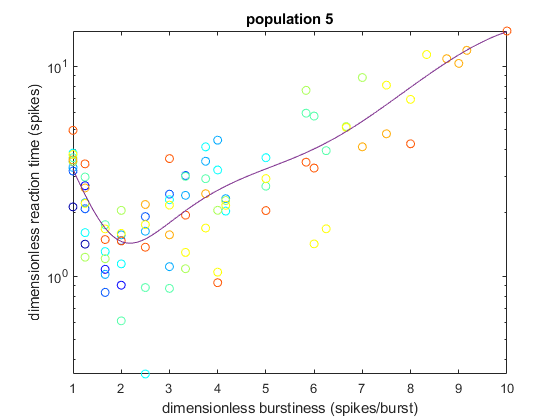

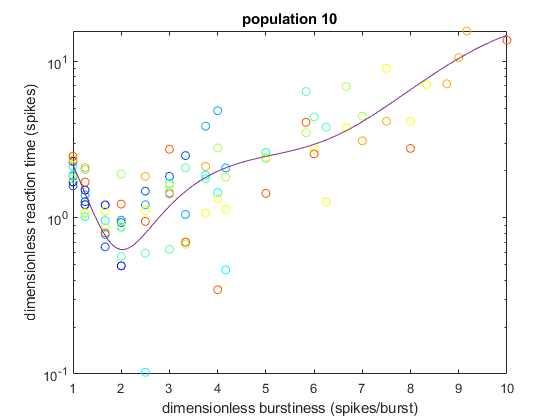

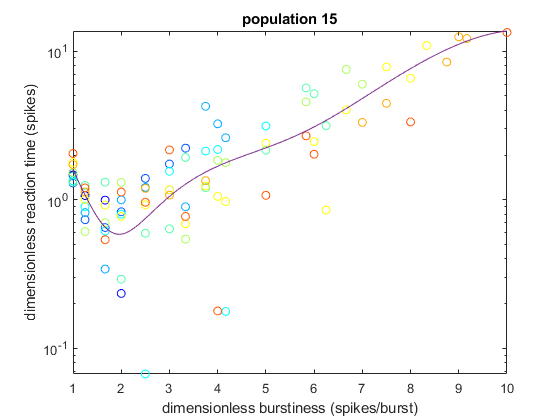

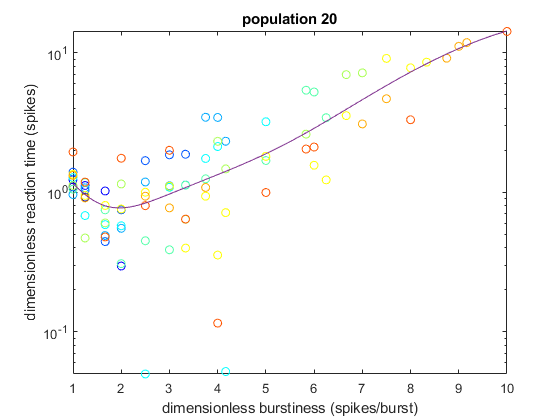

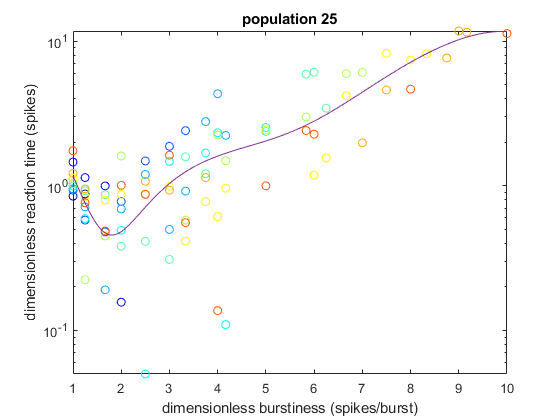

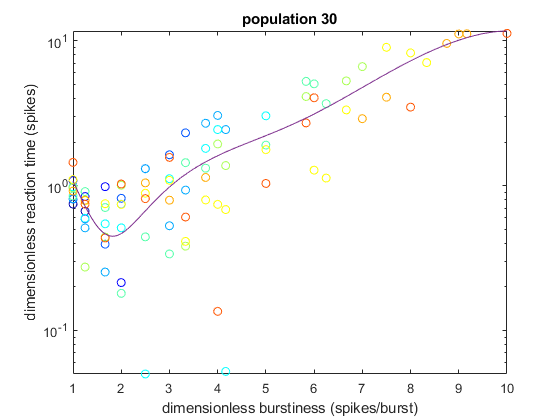

% generate a random color for each firing rate
mycolors = jet(10);
fr_vals = 10:10:100;
close all hidden;
P = zeros(npop,6); % preallocate matrix to hold polynomial coeff for each population
for k = 1:npop
    figure;
    c = C{k};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT(ii,jj) = c{ii,jj}.performance(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT = median(RT,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    hold on
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    p = polyfit(fit_x,fit_y,5);
    yy = polyval(p,xx);
    semilogy(xx,yy)
    hold off
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
    title(['population ', num2str(pop(k))])
    P(k,:) = p;
end

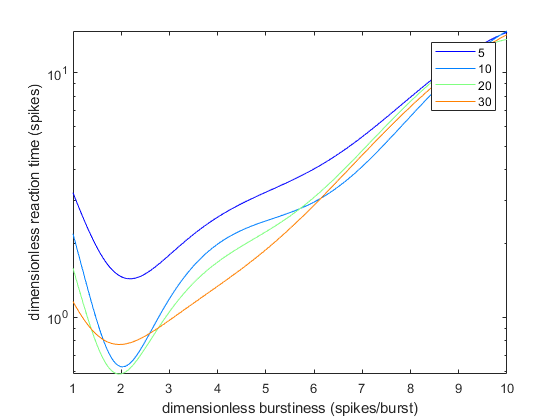

close all hidden;
mycolors2 = jet(npop);
mypop = [1 2 4 6];
for k = 1:length(mypop)
    xx = 1:0.01:10;
    p = P(k,:);
    yy = polyval(p,xx);
    semilogy(xx,yy,'color',mycolors2(mypop(k),:))
    hold on
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
end
hold off
legend('5','10','20','30')

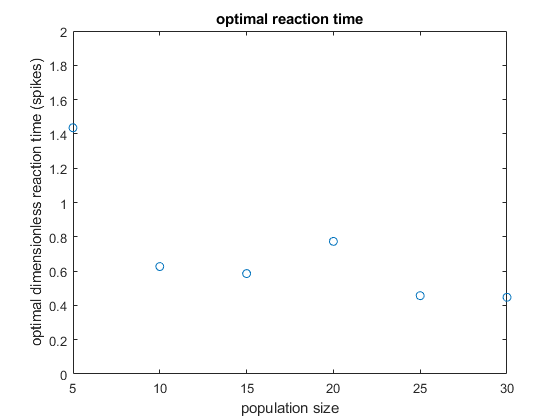

close all hidden;
optimal_burst_prediction = zeros(npop,1);
optimal_rt_prediction = zeros(npop,1);

for k = 1:npop
    xx = 1:0.01:10;
    p = P(k,:);
    yy = polyval(p,xx);
    [~,min_ind] = min(yy);    
    optimal_burst_prediction(k) = xx(min_ind);
    optimal_rt_prediction(k) = yy(min_ind);
end

plot(pop,optimal_rt_prediction, 'o')
ylim([0 2])
ylabel('optimal dimensionless reaction time (spikes)')
xlabel('population size')
title('optimal reaction time')

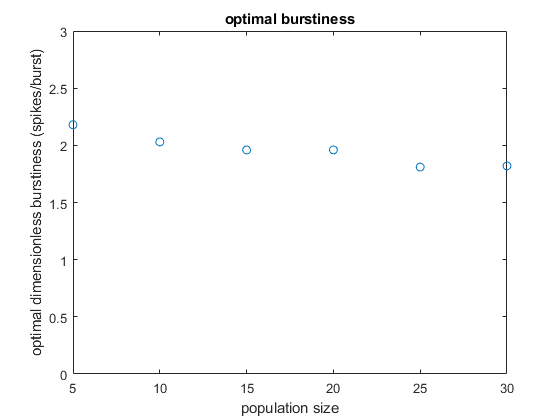


plot(pop,optimal_burst_prediction, 'o')
ylim([0 3])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('population size')
title('optimal burstiness')

## example plots in paper

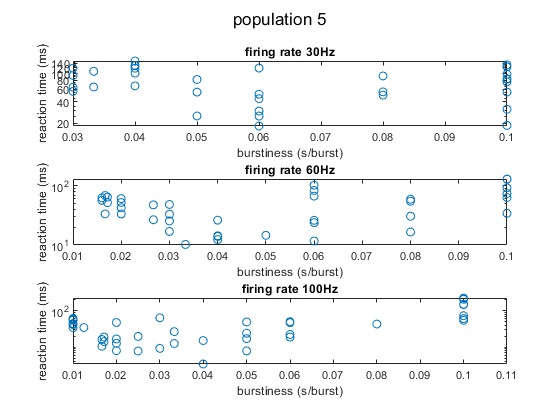

close all hidden;
vals = [30 60 100];
for j = 1:length(vals)
    c = C{1};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials
    RT = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT(ii,jj) = c{ii,jj}.performance(1,3);
        end
    end
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);
    k1 = params(:,3);
    burstiness = k1./lambda1;
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    RT = median(RT,2);
    rows = find(fr==vals(j));
    burstinessj = burstiness(rows);
    rt = RT(rows);
    subplot(3,1,j)
    semilogy(burstinessj,rt,'o')
    ylabel('reaction time (ms)')
    xlabel('burstiness (s/burst)')
    title(['firing rate ', num2str(vals(j)), 'Hz'])
end
sgtitle('population 5')

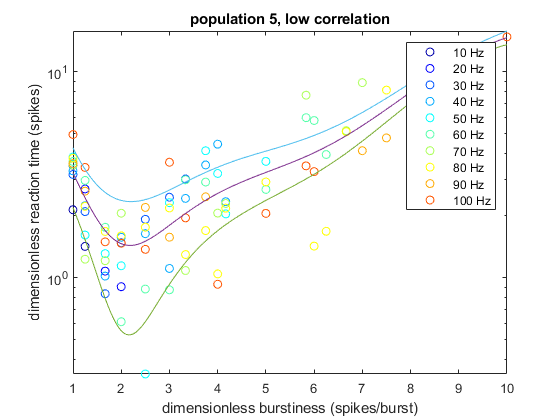

close all hidden;
y = RT.*fr_exact./1000;
x = fr2;

all_x = [];
all_y = [];
for i = 1:length(fr_vals)
    rows2 = find(fr == fr_vals(i));
    this_x = x(rows2);
    this_y = y(rows2);
    x_vals = unique(this_x);
    y_vals = zeros(length(x_vals),1);
    for j = 1:length(x_vals)
        y_vals(j) = median(this_y(this_x == x_vals(j)));
    end
    semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
    all_x = [all_x; x_vals];
    all_y = [all_y; y_vals];
    hold on
end
fit_x = unique(all_x);
fit_y = zeros(length(fit_x),1);
fit_error = zeros(length(fit_x),1);
for j = 1:length(fit_x)
    fit_y(j) = median(all_y(all_x == fit_x(j)));
    fit_error(j) = iqr(all_y(all_x == fit_x(j)));
end
xx = 1:0.01:10;
[p, S, mu] = polyfit(fit_x,fit_y,5);
[yy, delta] = polyval(p,xx,S, mu);
delta = 0.7.*delta;
semilogy(xx,yy)
hold on
semilogy(xx,yy-delta)
hold on
semilogy(xx,yy+delta)
hold off
ylabel('dimensionless reaction time (spikes)')
xlabel('dimensionless burstiness (spikes/burst)')
title('population 5, low correlation')
legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')